clear all
close all
run ../../../install.m

## 连接 zeroMQ

clear context socket; % 清除特定变量
javaaddpath('E:\00000科研资料-软体机器人控制\0000_Robot_SSM_MPC_FinalVersion_Exp\example\trunk\Trunk_LengthControl_experiment_feedback_withSpeed\jeromq-0.6.0.jar')

## 连接动捕SDK

ip = '127.0.0.1';
luster = LuMoSDKMPI(ip);

Loading LuMoSDKCAPI



if(luster.connect() == false)
    error("Run program failed.");
end

Initializing the SDK object...
The SDK object initialized successfully.


## 机器人平台参数-测量

phi = 15; % 靶球直径
h   = 20; % 靶球远端到平台基座的距离
c_bias = 24.5; % 机械臂基座到平台基座的距离
% h_basis = h - phi/2 ; % 基座靶球测到的基座坐标系偏移到机械臂基座坐标系
h_basis = h - phi/2 - c_bias ; % 基座靶球测到的基座坐标系偏移到机械臂基座坐标系


## 加载 trunk 控制模型信息

load('SSM_ROM8_Expe/outdof_endeff.mat','outdof_endeff')
load('SSM_ROM8_Expe/outdof_half.mat','outdof_half')
load('SSM_ROM8_Expe/Node_List.mat',"Node_List")
% load('SSM_ROM8_Expe/n.mat','n') % 有限元模型（2阶系统）的维度
load("SSM_ROM8_Expe/zd_proj.mat","zd_proj")
load("SSM_ROM8_Expe/t_list.mat" ,"t_list")

## 加载 SSM 

load("SSM_ROM8_Expe/auData.mat","auData")
n = 5574;

## MPC - 参数初始化（建议：重复实验从这里开始运行）

t0 = 0; T1 = t_list(end);
tf     = T1;

cont           = struct();
cont.constr_num= 6;
cont.Np        = 1;
cont.Q         = 1*diag([1e5, 1e5, 1e5, 1e3, 1e3, 1e3]);
cont.R         = 1e-2;

cont.dt        = 0.075;                                  % 单步步长
cont.u_lb      = repmat(-50 * ones(6,1), cont.Np, 1);
cont.u_ub      = repmat(+50 * ones(6,1), cont.Np, 1);
cont.outdof    = outdof_endeff;
cont.middof    = outdof_half;

cont.dist0     = CableLength_double_part(zeros(n,1),Node_List);
cont.Node_List = Node_List;
cont.n         = n;

constr_num     = cont.constr_num;                   % 控制数目
x_num          = length(auData.lamd); % 非线性维度;
cont.tf        = tf;

## 加载轨迹信息

cont.zd = zd_proj;
cont.td = t_list;

## 初始化SSM-MPC

% ================= Initial condition ===================
% Data saving

ssm_save      = struct();
ssm_save.pt_save = [];
ssm_save.zt_save = [];
ssm_save.ztfull_save = [];
ssm_save.ut_save = [];
save('ssm_save.mat', 'ssm_save')

z0   = zeros(2*n,1);
p0   = zeros(8,1);
t1   = t0;

% S0_guess = zeros(x_num,cont.Np);
% p_guess  = repmat(p0,1,cont.Np+1);
% u_guess  = zeros(cont.constr_num,cont.Np);

S0_opt   = zeros(x_num,cont.Np);
ut_opt   = zeros(cont.constr_num,cont.Np);

pk       = p0;
zk       = z0;

ssm_feedback = struct();
ssm_feedback.t        = t0;
ssm_feedback.k        = 1;
ssm_feedback.pk       = pk;
ssm_feedback.zk       = zk;
ssm_feedback.S0_opt   = S0_opt;
ssm_feedback.ut_opt   = ut_opt;


save('ssm_feedback.mat','ssm_feedback') 

## 建立位置参考 - 初始化（不受力）

# 测量点：末端 - 中端 - 第二段中某一点

% %%% 提取初始位姿 - 作为位移参考 %%%%
frameData = luster.receiveFrame();
markers   = frameData.allMarker;
rigid = frameData.allRigidbody; % base - mideff - endeff

global mark_ind

logical_inds = [markers.markerID] == 100027;
mark_ind     = find(logical_inds == 1)

mark_ind = 1


% 基座空间位置 - 固定不变，所以只需要提取一次
base          = rigid(1);
base_xyz      = [base.X, base.Y, base.Z];
base_xyz(:,2) = base_xyz(:,2) - h_basis;  % y方向 偏移到机械臂基座端
base_q        = [base.qw, base.qx, base.qy, base.qz];
R_B2G        = quat2dcm(base_q); % 全局坐标系转基座坐标系

% ============= 3 个反馈点 ==========================

% ========= 末端初始位置 ==========
endeff       = markers(mark_ind);
endeff_xyz   = [endeff.X, endeff.Y, endeff.Z];

delta_EB    = (endeff_xyz - base_xyz)' % 末端执行器 与 基座坐标系的差值，在G系中表示

delta_EB = 3×1 single 列向量
  108.2018
  444.5129
  -83.5822


pos_endeff_ref  = (R_B2G*delta_EB)' % 参考位置，相对基座的位置

pos_endeff_ref = 1×3 single 行向量
  103.4102   83.7397  445.6224



% ========= 中端初始位置 ==========
mideff       = rigid(2);
mideff_xyz   = [mideff.X, mideff.Y, mideff.Z];

delta_MB        = (mideff_xyz - base_xyz)' % 中端 与 基座坐标系的差值，在G系中表示

delta_MB = 3×1 single 列向量
  112.3229
  215.6489
  -86.2239


pos_mideff_ref  = (R_B2G*delta_MB)'    % 中端参考位置，相对基座的位置

pos_mideff_ref = 1×3 single 行向量
  109.9739   86.3280  216.8149



% ========= 第二段某测量点 ==========
feedback_Pt       = rigid(3);
feedback_pt_xyz   = [feedback_Pt.X, feedback_Pt.Y, feedback_Pt.Z];

delta_FBptB        = (feedback_pt_xyz - base_xyz)' % 中端 与 基座坐标系的差值，在G系中表示

delta_FBptB = 3×1 single 列向量
  111.5556
  287.7435
  -86.2987


pos_feedbackPt_ref  = (R_B2G*delta_FBptB)'    % 中端参考位置，相对基座的位置

pos_feedbackPt_ref = 1×3 single 行向量
  108.4367   86.4199  288.8972


% pos_feedbackPt_ref = [];
disp_fbPoint      =  (pos_feedbackPt_ref - pos_endeff_ref) ./ 1000; % 相对于末端的位移


% ========= 障碍物初始位置，相对于末端 ==========
obst          = rigid(4);
obst_xyz   = [obst.X, obst.Y, obst.Z];

delta_obst        = (obst_xyz - base_xyz)' % 中端 与 基座坐标系的差值，在G系中表示

delta_obst = 3×1 single 列向量
  120.1097
  431.6703
 -177.5611


pos_obst_ref  = (R_B2G*delta_obst)'    % 中端参考位置，相对基座的位置

pos_obst_ref = 1×3 single 行向量
  115.4113  177.7210  432.8846


disp_obst     = (pos_obst_ref - pos_endeff_ref) ./1000

disp_obst = 1×3 single 行向量
    0.0120    0.0940   -0.0127


## 避障系数

cont.pos_in         = [0; 0; 0.2225];
cont.pos_end        = [0; 0; 0.4400];

cont.pos_obstacle  = double(disp_obst)' + cont.pos_end;  % 障碍物位置
cont.R_obstacle    = 0.03; % 障碍物大小
alpha        = 2; % 安全系数
cont.d_safe  =  (alpha * cont.R_obstacle)^2;  % 安全距离

## 反馈测量点

% pos_feedbackPt      =  [0,0,0.32]';
pos_feedbackPt    = double(disp_fbPoint)' + cont.pos_end;  % 障碍物位置
load("SSM_ROM8_Expe/nodes_coord.mat", "nodes_coord")
dist              = vecnorm(nodes_coord - pos_feedbackPt, 2, 1);
[val,check_ind]   = min(dist);
outdof_feedbackPt = [check_ind*3-2, check_ind*3-1, check_ind*3]';

% % % 输出自由度编号 --- 绳索自由度编号
outdofs_for_Wp = [outdof_endeff;...  % 位移
                  outdof_half;...

                  outdof_endeff+n;...% 速度
                  outdof_half+n
                  ];

outdofs_for_FB = [outdof_endeff;...  % 位移
                  outdof_half;...
                  outdof_feedbackPt
                  ];


% 6根绳子的节点编号
cable1 = []; cable2 = []; cable3 = []; 
cable4 = []; cable5 = []; cable6 = []; 
for i = 2:17
    cable1 = [cable1; Node_List{1}{1,i}(4:6)];
    cable2 = [cable2; Node_List{1}{2,i}(4:6)];
    cable3 = [cable3; Node_List{1}{3,i}(4:6)];
end

for i = 2:10
    cable4 = [cable4; Node_List{2}{1,i}(4:6)];
    cable5 = [cable5; Node_List{2}{2,i}(4:6)];
    cable6 = [cable6; Node_List{2}{3,i}(4:6)];
end

cablesDofs_for_Wp = [cable1;...
                     cable2;...
                     cable3;...
                     cable4;...
                     cable5;...
                     cable6];

% % 计算 ssm w(p) 
load("SSM_ROM8_Expe/W_0.mat","W_0")
ssm_factor = 1.5;
W_0(2).coeffs            = W_0(2).coeffs           *ssm_factor;

% 提取对应自由度对应的Wp
W_0_for_out    = W_0;
W_0_for_cables = W_0;
W_0_for_FB     = W_0;

for i = 1:length(W_0)
    W_0_for_out(i).coeffs = W_0_for_out(i).coeffs(outdofs_for_Wp,:);
    W_0_for_FB(i).coeffs  = W_0_for_FB(i).coeffs(outdofs_for_FB,:);
    W_0_for_cables(i).coeffs = W_0_for_cables(i).coeffs(cablesDofs_for_Wp,:);
end


existingTimers = timerfindall;
if ~isempty(existingTimers)
    stop(existingTimers);
    delete(existingTimers);
end
num  = round((tf-t0)/cont.dt);
% num = 20;

## timer1：SSM-MPC

% ZeroMQ socket
context = org.zeromq.ZMQ.context(1);
socket = context.socket(org.zeromq.ZMQ.PUB);  
% socket.bind('tcp://*:5555');  % host 5555
socket.bind('tcp://*:5555');  % host 5555
disp('ZeroMQ Running');

ZeroMQ Running


global factor
global posi_save
posi_save = [];
global y_exprm
load('y_exprm.mat', 'y_exprm')
global pt_save
pt_save = [];

factor   = 1.3;
feedback = 0;

options = optimoptions('lsqnonlin', ...  % 通用无约束优化器
    'Algorithm', 'levenberg-marquardt',... % levenberg-marquardt, trust-region-reflective
    'Display', 'none', ...
    'SpecifyObjectiveGradient',false,...
    'MaxIterations', 3);
cont.opt_W     = 36;

timer1 = timer('ExecutionMode', 'fixedRate',...  %
          'Period', cont.dt,...                 
          'StartFcn', @(~,~) SSM_MPC_Start_Func,...  
          'TimerFcn', @(~,~) SSM_MPC_Actuator(cont,x_num,cont.constr_num,auData,W_0_for_out,W_0_for_cables,W_0_for_FB,socket,feedback,options),...                     % run actuator
          'StartDelay', 0,...
          'TasksToExecute', num);

## timer2：获取测量信息并输出测量数据  50 Hz

global t_exprm % y_exprm
t_exprm = [];
% y_exprm = [];

% cap_dt = cont.dt;
% num_cap = round(tf / cap_dt);

timer2 = timer('ExecutionMode', 'fixedRate',...  % 固定速率模式，按周期重复执行
          'Period', cont.dt,...                 % 周期为0.1秒
          'StartFcn', @(~,~) Dynamic_capture_Start_Func,...  % 初始化 t_i displ_endeff
          'TimerFcn', @(~,~) Dynamic_Capture(luster,base_xyz,pos_endeff_ref,pos_mideff_ref,pos_feedbackPt_ref, R_B2G),...                     % run actuator
          'StartDelay', cont.dt,...               % 立即启动，无延迟
          'TasksToExecute', num+1);       

## Run timer

% 采样时间设置为 0.1s 
% 开始 线程
start(timer2) % 先开始测量
start(timer1) % 开始控制

message_input = '';
while string(message_input)~="end"
    message_input = input('输入end结束线程： \n', 's')
    if strtrim(message_input)=="end"
        stop(timer1)
        delete(timer1)

        stop(timer2)
        delete(timer2)

        % 关闭 ZeroMQ 套接字
        socket.close();
        context.term();
        disp("线程关闭")
    end
end

message_input = 'end'

线程关闭


numnum = size(posi_save,1);

t = cont.dt:cont.dt:numnum*cont.dt;
zzd = zd_proj;
ut_save = posi_save';

save('t.mat','t')
save('zzd.mat','zzd')
% save('y_exprm.mat','y_exprm')
save('pt_save', 'pt_save')
save('ut_save.mat','ut_save')

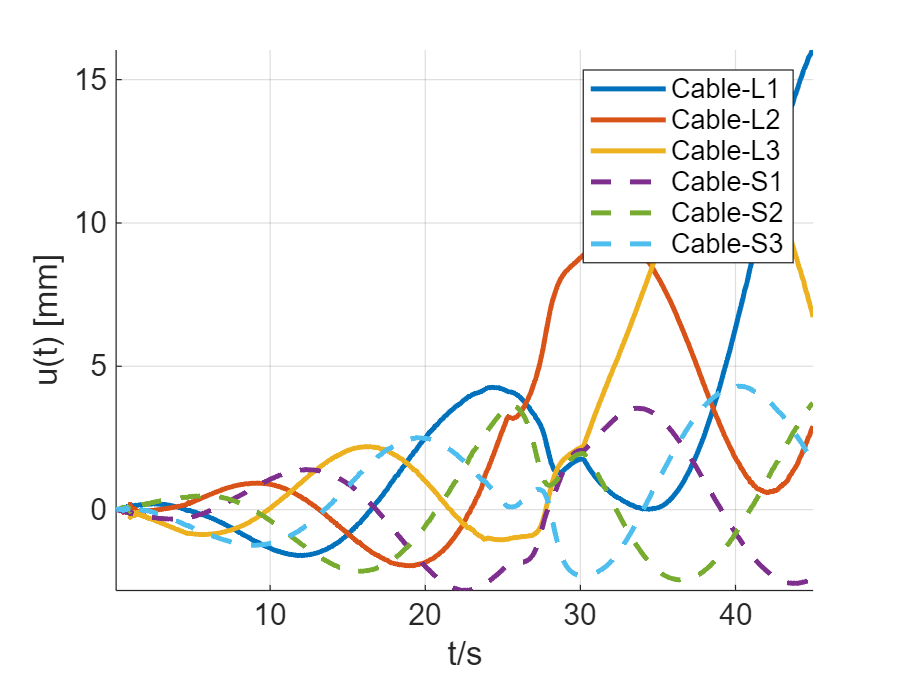

figure; hold on  
plot(t, ut_save(1:3,:),'-',LineWidth=2)
plot(t, ut_save(4:6,:),'--',LineWidth=2)
grid on, axis tight
set(gca,'FontSize',12); grid on, axis tight
legend(["Cable-L1","Cable-L2","Cable-L3","Cable-S1","Cable-S2","Cable-S3"])
xlabel('t/s')
ylabel('u(t) [mm]')

% figure; hold on  
% plot(t, y_exprm(2:end,2),LineWidth=2)
% grid on, axis tight
% set(gca,'FontSize',12); grid on, axis tight
% xlabel('t/s')
% ylabel('y(t) [mm]')

% figure; hold on  
% plot(t, y_exprm(2:end,4),LineWidth=2)
% grid on, axis tight
% set(gca,'FontSize',12); grid on, axis tight
% xlabel('t/s')
% ylabel('y(t) [mm]')
% 
% figure; hold on  
% plot(t, y_exprm(2:end,5),LineWidth=2)
% grid on, axis tight
% set(gca,'FontSize',12); grid on, axis tight
% xlabel('t/s')
% ylabel('y(t) [mm]')


% figure; hold on  
% plot(t, y_exprm(2:end,6),LineWidth=2)
% grid on, axis tight
% set(gca,'FontSize',12); grid on, axis tight
% xlabel('t/s')
% ylabel('y(t) [mm]')
% 
% figure; hold on  
% plot3(y_exprm(2:end,4), y_exprm(2:end,5), y_exprm(2:end,6),LineWidth=2)
% grid on, axis tight
% set(gca,'FontSize',12); grid on, axis tight
% xlabel('x/[mm]')
% ylabel('y/[mm]')
% zlabel('z/[mm]')
% view(3)
